% To analyze Victor's opto-stim data of "WhiteNoise" - imaging under
% continous movie stimulation

% ROI_Data.mat - saves ROI_data, rawResponse is the F signal
% relativeTime.mat - saves the timing of each frame
% markpointData.mat - Trigger saves the timing of all opto stim, Index saves the the R01 being stimulated

% Load the necessary data files
load('ROI_Data.mat');
load('relativeTime.mat');
load('markpointData.mat');

% make plot to look at traces
% figure; plot (relativeTime, ROI_Data(2).rawResponse);
% xlabel('Time (s)');
% ylabel('Response Amplitude');


## set up and extract data

% set up 
analysisWindowBefore = 8; 
analysisWindowAfter = 16;% number of frames before and after each optoStim for analysis
optoTime = [];
optoFrameNum = [];
optoTarget = [];
rawResponseAtOpto = [];

% sort through each opti stim
for optoIndex = 1:size(markpointData, 1)
    optoTime(optoIndex) = markpointData(optoIndex).Trigger;
    optoFrameNum(optoIndex) = find(relativeTime >= optoTime(optoIndex), 1, 'first'); % find the first frame after the opto frame
    tempWindow = (optoFrameNum(optoIndex)-analysisWindowBefore):(optoFrameNum(optoIndex)+analysisWindowAfter-1); % the frames to include in analysis
    optoTarget(optoIndex) = markpointData(optoIndex).Index;

    % sort through each ROI
    for roiIndex = 1:size(ROI_Data,1)
        % Extract the raw response for the current ROI at the opto frame
        rawResponseAtOpto(roiIndex, optoIndex, :) = ROI_Data(roiIndex).rawResponse(tempWindow);
        % figure; plot(squeeze(rawResponseAtOpto(roiIndex, optoIndex, :)));
        
    end   
end
% now rawResponseAtOpto saves all ROI's optoStim response

## Now find those in response to the same Opto Target stimulation

numTargets = numel(unique(optoTarget)); % how many targets were opto stimulated

for targetIndex = 1:numTargets
    targetID = optoTarget(targetIndex);
    tempIndex = find(optoTarget==targetID);
    % Average the raw responses for the current target for each ROI
    for roiIndex = 1:size(ROI_Data,1)
        tempData = squeeze(rawResponseAtOpto(roiIndex, tempIndex, :)); % 2D matrix of all trials when stimulating this target
        avgResponse(roiIndex, targetIndex, :) = mean(tempData, 1);
        % figure; subplot(10,11,roiIndex); hold on; 
        % plot(tempData', 'LineWidth', 0.2, 'Color', 'k');
        % plot(squeeze(avgResponse(roiIndex, targetIndex, :)), 'LineWidth', 1, 'Color', 'g');
        % xline(analysisWindowBefore+0.5, '--r', 'OptpStim');
        tempF0 = mean(squeeze(avgResponse(roiIndex, targetIndex, 1:analysisWindowBefore)));
        avgResponseN(roiIndex, targetIndex, :) = (avgResponse(roiIndex, targetIndex, :) - tempF0)./tempF0; % Normalize
    end     
end


## make figures

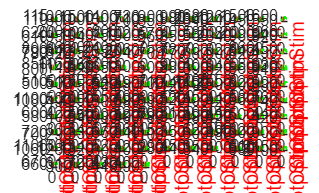

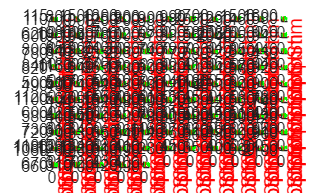

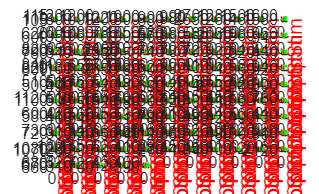

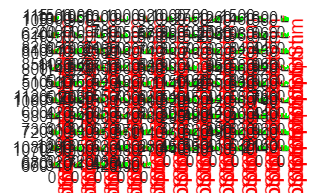

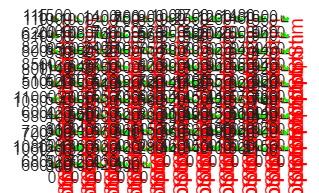

for targetIndex = 1:numTargets
    figID = figure;
    for roiIndex = 1:size(ROI_Data,1)
        figure(figID);
        subplot(10,11,roiIndex); hold on; 
        plot(squeeze(avgResponseN(roiIndex, targetIndex, :)), 'LineWidth', 1, 'Color', 'k');
        xline(analysisWindowBefore+0.5, '--r');
        % xline(analysisWindowBefore+0.5, '--r', 'OptpStim');
    end     
    ax = findall(gcf, 'type', 'axes');
    xlim(ax, [0 25])
    ylim(ax, [-0.1, 0.1]);

end